syms thp J1 J2 R R2 M s b K fa g w thp thpp wp th

wp=(1/(J1+(J2*R^2)/(R2^2)+M*R^2))*(-b*w-K*th*R^2-((b*th*R^2)/R2^2)-R*(fa+M*g))

$$wp = -\frac{b\,w+R\,\left(\mathrm{fa}+M\,g\right)+K\,R^{2}\,\mathrm{th}+\frac{R^{2}\,b\,\mathrm{th}}{{R_{2}}^{2}}}{J_{1}+M\,R^{2}+\frac{J_{2}\,R^{2}}{{R_{2}}^{2}}}$$

thp=w

$$thp = w$$

xe=[w,th]

$$xe = \left(\begin{array}{cc} w & \mathrm{th} \end{array}\right)$$

y=th

$$y = \mathrm{th}$$


A=jacobian([wp,thp],xe)

$$A = \left(\begin{array}{cc} -\frac{b}{J_{1}+M\,R^{2}+\frac{J_{2}\,R^{2}}{{R_{2}}^{2}}} & -\frac{K\,R^{2}+\frac{R^{2}\,b}{{R_{2}}^{2}}}{J_{1}+M\,R^{2}+\frac{J_{2}\,R^{2}}{{R_{2}}^{2}}}\\ 1 & 0 \end{array}\right)$$

B=jacobian([wp,thp],fa)

$$B = \left(\begin{array}{c} -\frac{R}{J_{1}+M\,R^{2}+\frac{J_{2}\,R^{2}}{{R_{2}}^{2}}}\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

D=jacobian(y,fa)

$$D = 0$$


Fs=C*(inv(s*eye(2)-A))*B+D

$$Fs = -\frac{R\,\left(M\,R^{2}\,{R_{2}}^{2}+J_{2}\,R^{2}+J_{1}\,{R_{2}}^{2}\right)}{\left(J_{1}+M\,R^{2}+\frac{J_{2}\,R^{2}}{{R_{2}}^{2}}\right)\,\left(M\,R^{2}\,{R_{2}}^{2}\,s^{2}+K\,R^{2}\,{R_{2}}^{2}+J_{2}\,R^{2}\,s^{2}+b\,R^{2}+J_{1}\,{R_{2}}^{2}\,s^{2}+b\,{R_{2}}^{2}\,s\right)}$$

J1=0.1

J1 = 0.1000

J2=0.1

J2 = 0.1000

R=0.5

R = 0.5000

R2=0.25

R2 = 0.2500

K=1

K = 1

g=9.81

g = 9.8100

M=0.5

M = 0.5000

b=0.1

b = 0.1000


A=double(eval(A))

A =    -0.1600   -1.0400
    1.0000         0


B=double(eval(B))

B =    -0.8000
         0


C=double(eval(C))

C =      0     1


D=double(eval(D))

D = 0


[num,den]=ss2tf(A,B,C,D)

num =          0         0   -0.8000


den =     1.0000    0.1600    1.0400


ft=tf(num,den)

ft =
 
         -0.8
  -------------------
  s^2 + 0.16 s + 1.04
 
Continuous-time transfer function.



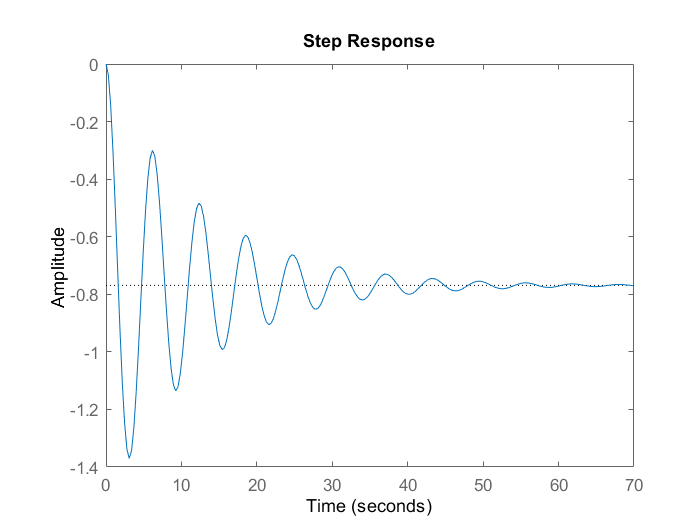

step(ft)

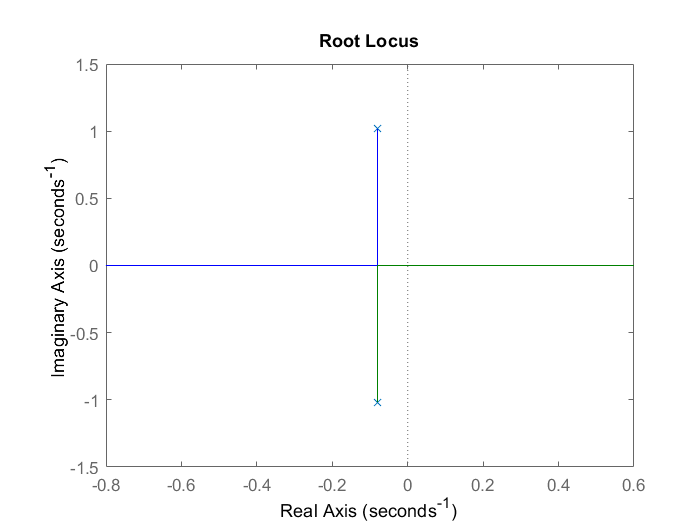

rlocus(ft)

roots(den)

ans =   -0.0800 + 1.0167i
  -0.0800 - 1.0167i


%%% Compensador Rampa
den

den =     1.0000    0.1600    1.0400


denRam=[den(1) den(2) den(3) 0 0]

denRam =     1.0000    0.1600    1.0400         0         0


syms s
LazoCerr=simplify((num(3)/(denRam(1)*s^4+denRam(2)*s^3+denRam(3)*s^2+denRam(2)*s+denRam(1)))/(1+(num(3)/(denRam(1)*s^4+denRam(2)*s^3+denRam(3)*s^2+denRam(2)*s+denRam(1)))))

$$LazoCerr = -\frac{20}{25\,s^{4}+4\,s^{3}+26\,s^{2}+4\,s+5}$$

denLazCerr=[1 2/15 13/15 2/15 5/15]

denLazCerr =     1.0000    0.1333    0.8667    0.1333    0.3333


ts=52

ts = 52

zeta=0.8

zeta = 0.8000

wn=4/(zeta*ts)

wn = 0.0962

pd=conv([1 2*zeta*wn wn^2],[1 10*zeta*wn])

pd =     1.0000    0.9231    0.1276    0.0071


pd=conv(pd,[1 10*zeta*wn])

pd =     1.0000    1.6923    0.8376    0.1053    0.0055


lcr=roots(pd)

lcr =   -0.7692 + 0.0000i
  -0.7692 + 0.0000i
  -0.0769 + 0.0577i
  -0.0769 - 0.0577i


s=lcr(3)

s = -0.0769 + 0.0577i

sa=eval(LazoCerr)

sa = -4.2025 + 0.0019i

modS=sqrt((real(sa))^2+(imag(sa))^2)

modS = 4.2025

theta=atan2d(imag(sa),real(sa))

theta = 179.9738

if theta<0
    theta=360+theta
end
AngComp=180-theta

AngComp = 0.0262

if AngComp<0
  AngComp=360+AngComp 
end
n2=1;
while abs(AngComp/n2)>60
   n2=n2+1; 
end
n2

n2 = 1

AngCompU=AngComp/n2

AngCompU = 0.0262

phiAMed=AngCompU/2

phiAMed = 0.0131

gamma1=atan2d(abs(imag(s)),abs(real(s)))

gamma1 = 36.8699

betaa=180-gamma1

betaa = 143.1301

betaMed=betaa/2

betaMed = 71.5651

gamma2=betaMed-phiAMed

gamma2 = 71.5519

gamma3=180-gamma1-gamma2

gamma3 = 71.5782

cerooRam=(modS*sind(gamma2))/(sind(gamma3))

cerooRam = 4.2019

gamma4=2*phiAMed+gamma2

gamma4 = 71.5782

gamma5=180-2*phiAMed-gamma2-gamma1

gamma5 = 71.5519

poloRam=(modS*sind(gamma4))/(sind(gamma5))

poloRam = 4.2031

syms k
ps=(num(3)/(denRam(1)*s^4+denRam(2)*s^3+denRam(3)*s^2+denRam(4)*s+denRam(5)))*((k*(s+cerooRam)^n2)/((s+poloRam)^n2))

$$ps = k\,\left(-\frac{251753527650693446444232935746449797167234118759}{10696589908949826288022786171131581186407661568}-\frac{1724127290157922919747866654912492382342975260841}{21393179817899652576045572342263162372815323136}\,\mathrm{i}\right)$$

Kram=double(solve(abs(ps)==1,k))

Kram = 0.0119

for k=1:n2
    rampCER(k)=-cerooRam;
    rampPOL(k)=-poloRam;
end
cerooRam

cerooRam = 4.2019

poloRam

poloRam = 4.2031

Kram=Kram^(1/n2)/n2

Kram = 0.0119

Kram

Kram = 0.0119

%%PID CONTINUO Y PID CONT-DISCRETO
kd1=-2.37298577

kd1 = -2.3730

kp=0.00900902956

kp = 0.0090

ki=-0.164429284

ki = -0.1644

ki2=-0.00866283566

ki2 = -0.0087

ftRam=tf([num(3)],denRam)

ftRam =
 
            -0.8
  -------------------------
  s^4 + 0.16 s^3 + 1.04 s^2
 
Continuous-time transfer function.



[mag,phase,wout] = bode(ftRam);
n=1;
while true
    if 20*log10(mag(:,:,n))>20*log10(mag(:,:,1))-3%
        n=n+1;
    else
        break
    end
end
wc=wout(n,1)

wc = 0.1334

wMuestr=wc/20

wMuestr = 0.0067

ftPID=tf([kd1,kp,ki,ki2],[0,1,0,0])

ftPID =
 
  -2.373 s^3 + 0.009009 s^2 - 0.1644 s - 0.008663
  -----------------------------------------------
                        s^2
 
Continuous-time transfer function.



ftDisc=c2d(ft,wMuestr,'tustin')

ftDisc =
 
  -8.889e-06 z^2 - 1.778e-05 z - 8.889e-06
  ----------------------------------------
           z^2 - 1.999 z + 0.9989
 
Sample time: 0.0066684 seconds
Discrete-time transfer function.



ftPIDdisc=c2d(ftPID,wMuestr,'tustin')

ftPIDdisc =
 
  -711.7 z^3 + 2135 z^2 - 2135 z + 711.7
  --------------------------------------
            z^3 - z^2 - z + 1
 
Sample time: 0.0066684 seconds
Discrete-time transfer function.



%PID DISCRETO
Bd=ftDisc.Numerator{1,1}

Bd = 	1.0e+-4 *

   -0.0889   -0.1778   -0.0889


Ad=ftDisc.Denominator{1,1}

Ad =     1.0000   -1.9989    0.9989


%funcion a la z^-1
Ad=flip(Ad)

Ad =     0.9989   -1.9989    1.0000


Bd=flip(Bd)

Bd = 	1.0e+-4 *

   -0.0889   -0.1778   -0.0889


%PID
syms r0 r1 r2 r3 Z
pidDisc=(r0+r1*Z^-1+r2*Z^-2+r3*Z^-3)/((1-Z^-1)^2)

$$pidDisc = \frac{r_{0}+\frac{r_{1}}{Z}+\frac{r_{2}}{Z^{2}}+\frac{r_{3}}{Z^{3}}}{{\left(\frac{1}{Z}-1\right)}^{2}}$$

ftZm1=(Bd(1)*Z^-2+Bd(2)*Z^-1+Bd(3))/(Ad(1)*Z^-2+Ad(2)*Z^-1+Ad(3))

$$ftZm1 = -\frac{\frac{655869766855217}{36893488147419103232\,Z}+\frac{655869766855217}{73786976294838206464\,Z^{2}}+\frac{655869766855217}{73786976294838206464}}{\frac{562349643665883}{562949953421312\,Z^{2}}-\frac{4501094307453161}{2251799813685248\,Z}+1}$$

[BB,AA]=numden(ftZm1)

$$BB = -655869766855217\,Z^{2}-1311739533710434\,Z-655869766855217$$

$$AA = 73786976294838206464\,Z^{2}-147491858266625179648\,Z+73708292494574616576$$

[RR,SS]=numden(pidDisc)

$$RR = r_{0}\,Z^{3}+r_{1}\,Z^{2}+r_{2}\,Z+r_{3}$$

$$SS = Z\,{\left(Z-1\right)}^{2}$$

LazoCerrDisc=(BB*RR)/(AA*SS+BB*RR)

$$LazoCerrDisc = \frac{\left(655869766855217\,Z^{2}+1311739533710434\,Z+655869766855217\right)\,\left(r_{0}\,Z^{3}+r_{1}\,Z^{2}+r_{2}\,Z+r_{3}\right)}{\left(655869766855217\,Z^{2}+1311739533710434\,Z+655869766855217\right)\,\left(r_{0}\,Z^{3}+r_{1}\,Z^{2}+r_{2}\,Z+r_{3}\right)-Z\,{\left(Z-1\right)}^{2}\,\left(73786976294838206464\,Z^{2}-147491858266625179648\,Z+73708292494574616576\right)}$$

[n,d]=numden(LazoCerrDisc)

$$n = 655869766855217\,\left(Z^{2}+2\,Z+1\right)\,\left(r_{0}\,Z^{3}+r_{1}\,Z^{2}+r_{2}\,Z+r_{3}\right)$$

$$d = 655869766855217\,r_{3}-73708292494574616576\,Z+655869766855217\,Z\,r_{2}+1311739533710434\,Z\,r_{3}+655869766855217\,Z^{2}\,r_{1}+655869766855217\,Z^{3}\,r_{0}+1311739533710434\,Z^{2}\,r_{2}+1311739533710434\,Z^{3}\,r_{1}+1311739533710434\,Z^{4}\,r_{0}+655869766855217\,Z^{2}\,r_{3}+655869766855217\,Z^{3}\,r_{2}+655869766855217\,Z^{4}\,r_{1}+655869766855217\,Z^{5}\,r_{0}+294908443255774412800\,Z^{2}-442478985322663182336\,Z^{3}+295065810856301592576\,Z^{4}-73786976294838206464\,Z^{5}$$

%K=[1,0,0,0;-1+d1,]
n=flip(coeffs(n,Z))

$$n = \left(\begin{array}{cccccc} 655869766855217\,r_{0} & 1311739533710434\,r_{0}+655869766855217\,r_{1} & 655869766855217\,r_{0}+1311739533710434\,r_{1}+655869766855217\,r_{2} & 655869766855217\,r_{1}+1311739533710434\,r_{2}+655869766855217\,r_{3} & 655869766855217\,r_{2}+1311739533710434\,r_{3} & 655869766855217\,r_{3} \end{array}\right)$$

d=flip(coeffs(d,Z))

$$d = \left(\begin{array}{cccccc} 655869766855217\,r_{0}-73786976294838206464 & 1311739533710434\,r_{0}+655869766855217\,r_{1}+295065810856301592576 & 655869766855217\,r_{0}+1311739533710434\,r_{1}+655869766855217\,r_{2}-442478985322663182336 & 655869766855217\,r_{1}+1311739533710434\,r_{2}+655869766855217\,r_{3}+294908443255774412800 & 655869766855217\,r_{2}+1311739533710434\,r_{3}-73708292494574616576 & 655869766855217\,r_{3} \end{array}\right)$$

p1=-2*exp(-2*zeta*wn*wMuestr)*cos(wn*wMuestr*sqrt(1-zeta^2))

p1 = -1.9979

p2=exp(-2*zeta*wn*wMuestr)

p2 = 0.9990

PMF=1+p1*Z^-1+p2*Z^-2

$$PMF = \frac{8997963424729675}{9007199254740992\,Z^{2}}-\frac{8997962758851795}{4503599627370496\,Z}+1$$

PFMd=conv([1 p1 p2],[1 -0.2]);
PFMd=conv(PFMd,[1 -0.2]);
PFMd=conv(PFMd,[1 -0.2])

PFMd =     1.0000   -2.5979    2.3177   -0.8471    0.1359   -0.0080


%RETRO DE ESTADOS
%%%Servosistema Escalon
AempaqEsc=[A,zeros(2,1),zeros(2,1);zeros(1,2),0,1;-C,0,0]

AempaqEsc =    -0.1600   -1.0400         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0   -1.0000         0         0


BempaqEsc=[B;0;0]

BempaqEsc =    -0.8000
         0
         0
         0


psd=[1 2*zeta*wn wn^2]

psd =     1.0000    0.1538    0.0092


PolosEsc=roots(psd)

PolosEsc =   -0.0769 + 0.0577i
  -0.0769 - 0.0577i


PolosEsc=conv(PolosEsc,[1 10*zeta*wn])

PolosEsc =   -0.0769 + 0.0577i  -0.1361 - 0.0133i  -0.0592 - 0.0444i


PolosEsc=conv(PolosEsc,[1 10*zeta*wn])

PolosEsc =   -0.0769 + 0.0577i  -0.1953 + 0.0311i  -0.1639 - 0.0546i  -0.0455 - 0.0341i


%PolosEsc=conv(PolosEsc,[1 10*zeta*wn])
Kesc=acker(AempaqEsc,BempaqEsc,PolosEsc)

Kesc =    -0.4020    1.1954    0.0002    0.0078


%Obs
tsa=ts/10;
wna=4/(tsa*zeta)

wna = 0.9615

obs=[C;C*A]

obs =      0     1
     1     0


det(obs)

ans = -1

pdo=[1 2*wna*zeta wna^2]

pdo =     1.0000    1.5385    0.9246


phia= pdo(1)*A^2+pdo(2)*A+eye(2)*pdo(3)

phia =    -0.3360   -1.4336
    1.3785   -0.1154


Lesc=phia*(inv(obs))*[0;1]

Lesc =    -0.3360
    1.3785
